### Linear Algebra and Programming Skills

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Calculating a root of a polynomial function using Newton's method

[Newton's method](https://en.wikipedia.org/wiki/Newton%27s_method) is a numerical algorithm for finding the root of a polynomial function. Let $f$ be a polynomial function which has a root at $x$ such that $f(x)=0$ then $x$ can be approximated using the iterative scheme

$x_{n+1} = x_n - \frac{f(x_n)}{f'(x_n)}$,

where $f'$ is the derviative of $f$. The scheme is started with an initial guess value $x_0$.

For example consider the function $f(x) = x^2 - 4x - 7$. Here $f'(x) = 2x - 4$ so Newton's method for this function is

$x_{n+1} = x_n - \frac{x_n^2 - 4x_n - 7}{2x_n - 4}$,

and using a starting value of $x_0=5$ we have


$$x_0=5, \\
x_1=5 - \frac{5^2 - 4(5)-7}{2(5)-4} = 5.333333, \\
x_2 = 5.333333 - \frac{5.333333^2 - 4(5.333333) - 4}{2(5.333333)-4} = 5.316667, \\
x_3=5.316667 - \frac{5.316667^2 - 4(5.316667) - 7}{2(5.316667)-4} = 5.316625, \\
x_4 = 5.316625 - \frac{5.316625^2 - 4(5.316625)-7}{2(5.316625)-4} = 5.316625.$$


The difference in the values obtained in the last two iterations agree to six decimal places so we know this is close to the actual root. When using numerical methods, we use a **convergence tolerance** $tol$ which is some small number and we cease iterations when $|x_{n+1} - x_n| < tol$. The smaller the value of $tol$ the more accurate our approximation is but will require more iterations, and therefore computational effort, to calculate.

The program below uses Newton's method to find this root. Note that using functions to calculate $f(x)$ and $f\prime (x)$ means that we can easily adapt it to find the roots of other polynomial functions.

% Define function and its derivative (using inline function definitions)
f = @(x) x .^ 2 - 4 * x - 7;
df = @(x) 2 * x - 4;

% Define parameters
maxiter = 100;            % maximum iteration limit
tol = 5e-6;               % convergence tolerange
x = zeros(maxiter+1, 1);  % array containing the estimates of the root
x(1) = 5;                 % starting value

% Iteration loop
for n = 1 : maxiter
    
    % Calculate new value of x using Newton's method
    x(n+1) = x(n) - f(x(n)) / df(x(n));
    
    % Check for convergence
    if abs(x(n+1) - x(n)) < tol
        break
    end
    
end

% Trim x array
x = x(1:n+1);

% Print a table containing the estimates of the root
table = '  n     x_n\n--------------\n';
for i = 1 : n + 1
    table = [ table, sprintf('%3i %10.6f\n', i - 1, x(i)) ];
end
fprintf(table);

  n     x_n
--------------
  0   5.000000
  1   5.333333
  2   5.316667
  3   5.316625
  4   5.316625


We can plot the function to check whether $f(x)=0$.

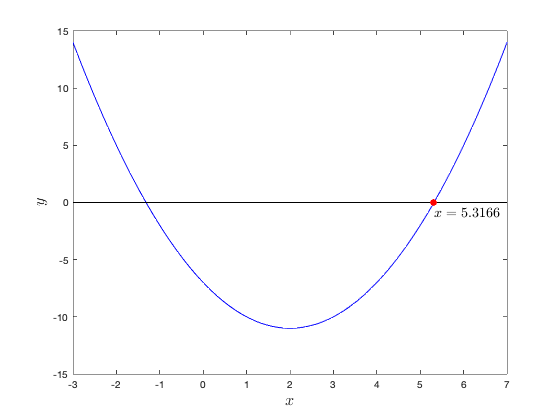

% Plot function and root
xmin = -3; xmax = 7;
x1 = linspace(xmin, xmax, 100);

plot(x1, f(x1), 'b-')
hold on
plot([xmin, xmax], [0, 0], 'k-')
plot(x(n+1), 0, 'ro', 'MarkerFaceColor', 'r')
hold off

axis([xmin, xmax, -15, 15])
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 16)
text(x(n+1), -1, sprintf('$x=%1.4f$', x(n+1)),  'Interpreter', 'latex', 'FontSize', 14)